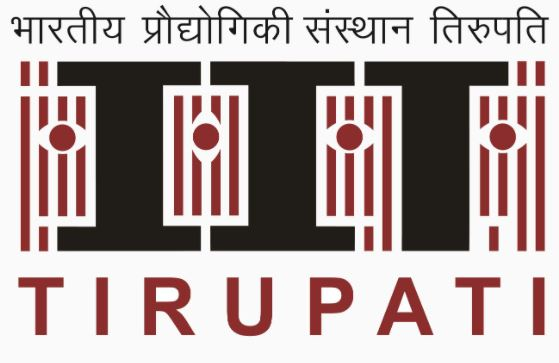

### **Digital Signal Processing Laboratory**

**LabSheet-06**

Name: Suriyaa MM

Roll Number: EE23B054

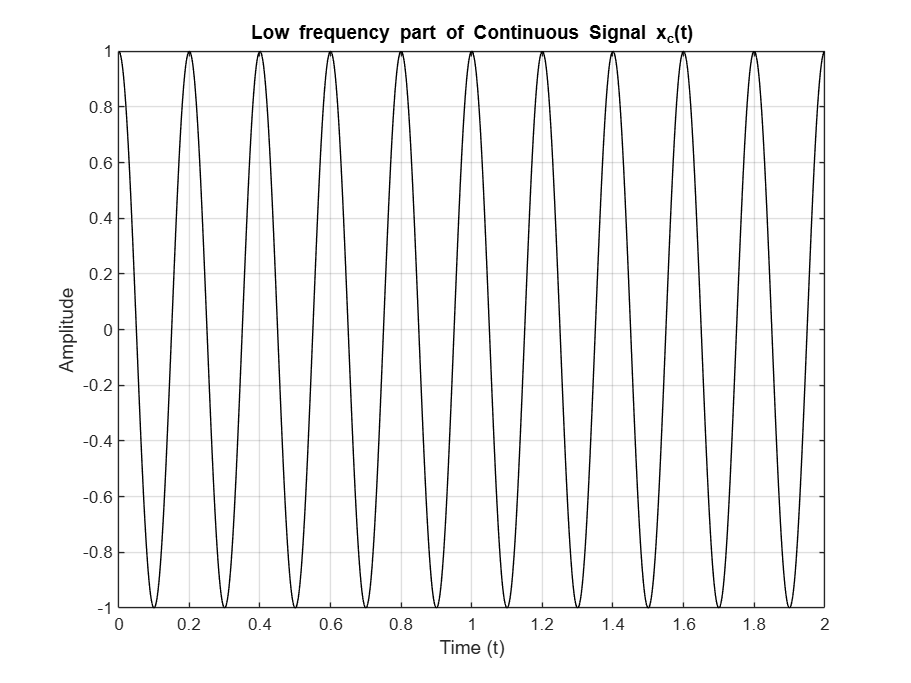

% Parameters
omega_c = 2 * pi * 10;       % Cutoff frequency (rad/s)
omega_1 = 2 * pi * 5;         % Frequency of low-frequency cosine (rad/s)
omega_2 = 2 * pi * 15;        % Frequency of high-frequency cosine (rad/s)
omega_s = 2 * (omega_2) * 2;  % Sampling frequency (rad/s)
T = 2 * pi / omega_s;         % Sampling period
Tmax = 2;                     % Max time for simulation
dt = 0.001;                   % Time step for continuous signal

% Time vector and continuous input signal
t = 0:dt:Tmax;
x_c = cos(omega_1 * t) + cos(omega_2 * t);
x_c_l = cos(omega_1 * t);  % Low-frequency component
x_c_h = cos(omega_2 * t);  % High-frequency component

figure;
plot(t, x_c_l, 'k');
xlabel('Time (t)');
ylabel('Amplitude');
title('Low frequency part of Continuous Signal x_c(t)');
grid on;

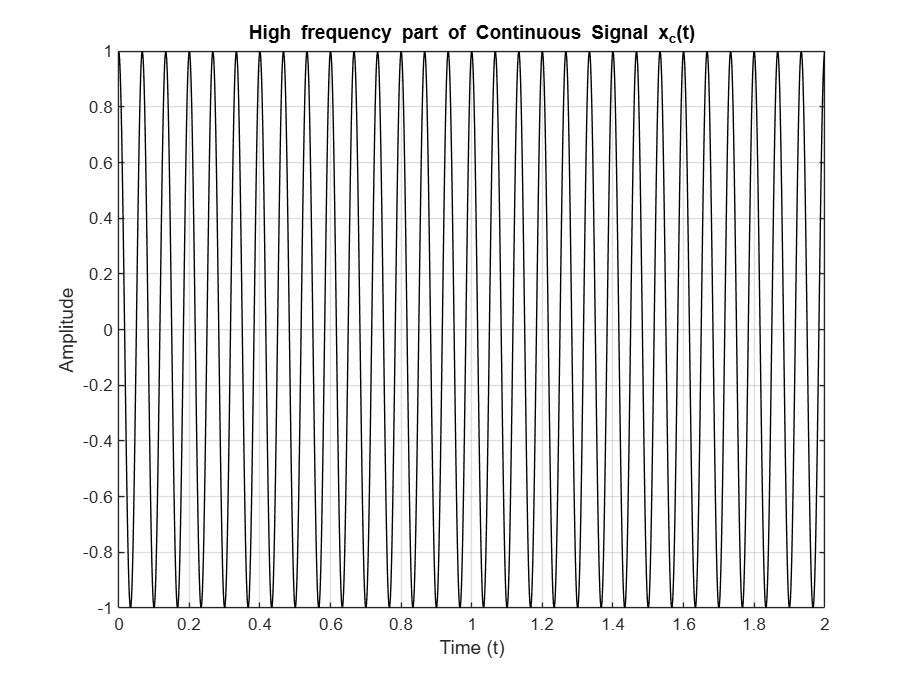


figure;
plot(t, x_c_h, 'k');
xlabel('Time (t)');
ylabel('Amplitude');
title('High frequency part of Continuous Signal x_c(t)');
grid on;

 **Sampling the Continuous Signal**

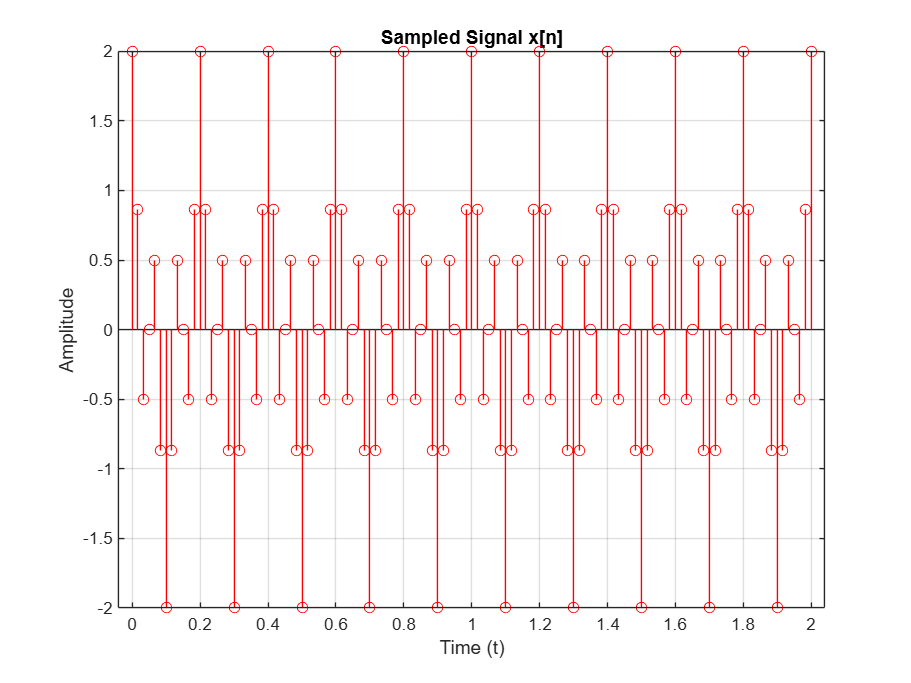

n = 0:floor(Tmax / T);
x_s = cos(omega_1 * n * T) + cos(omega_2 * n * T);
figure;
stem(n * T, x_s, 'r');
xlabel('Time (t)');
ylabel('Amplitude');
title('Sampled Signal x[n]');
grid on;

Low-Pass Filter Impulse Response

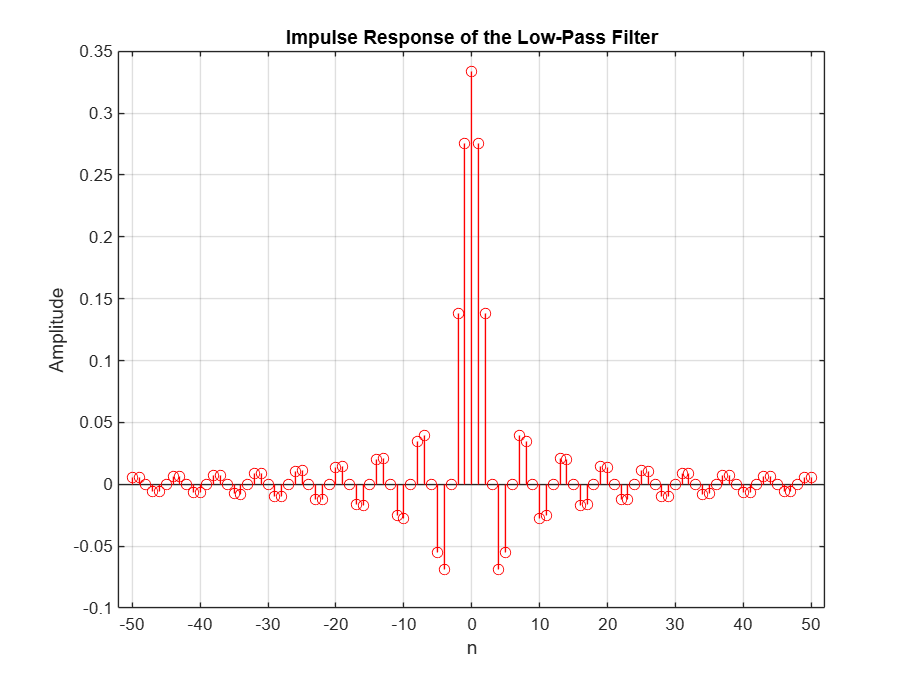

W_c = omega_c * T;      % Discrete-time cutoff frequency
M = 50;                 % Filter length
n_filter = -M:M;
h_lp = (W_c/pi) * sinc(W_c * n_filter/pi);
figure;
stem(n_filter, h_lp, 'r');
xlabel('n');
ylabel('Amplitude');
title('Impulse Response of the Low-Pass Filter');
grid on;

Filtering the Sampled Signal

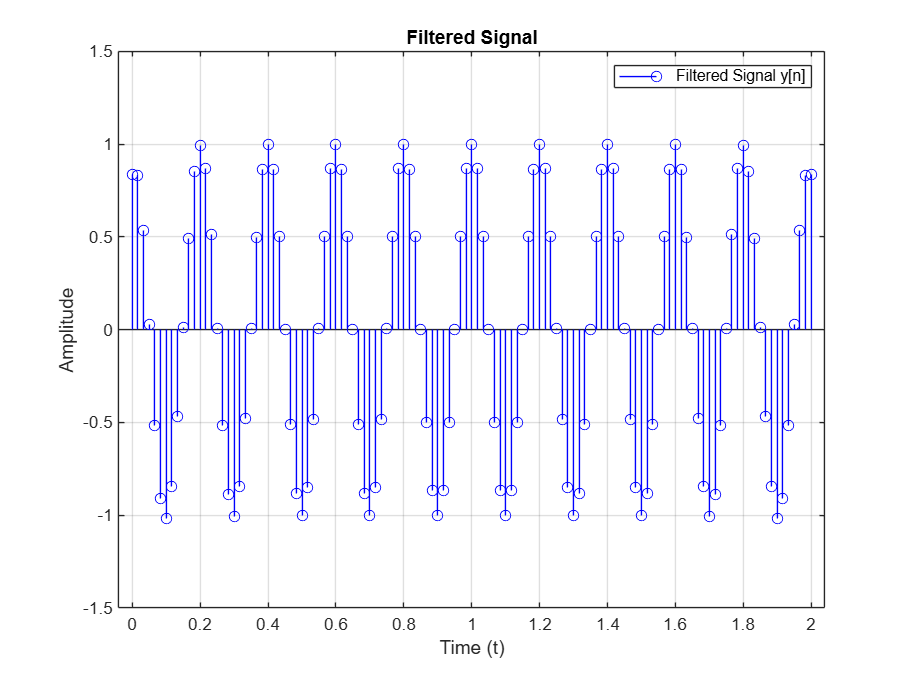

y_n = conv(x_s, h_lp, 'same');
figure;
stem(n * T, y_n, 'b');
xlabel('Time (t)');
ylabel('Amplitude');
title('Filtered Signal');
legend('Filtered Signal y[n]');
grid on;

Generating Narrow Pulses for Filtered Samples

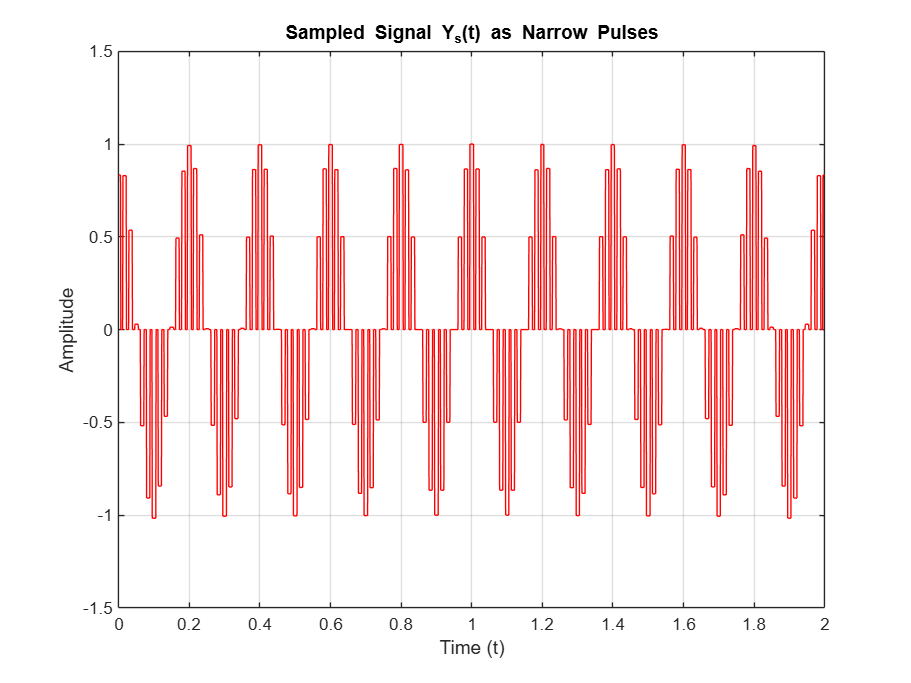

dt = 0.001;
t_cont = 0:dt:Tmax;
Y_s = zeros(size(t_cont));
pulse_width = 0.01;
for i = 1:length(n)
    pulse_start = n(i) * T - pulse_width / 2;
    pulse_end = n(i) * T + pulse_width / 2;
    indices = find(t_cont >= pulse_start & t_cont <= pulse_end);
    Y_s(indices) = y_n(i);
end
figure;
plot(t_cont, Y_s, 'r');
xlabel('Time (t)');
ylabel('Amplitude');
title('Sampled Signal Y_s(t) as Narrow Pulses');
grid on;

Reconstruction Using Sinc Interpolation

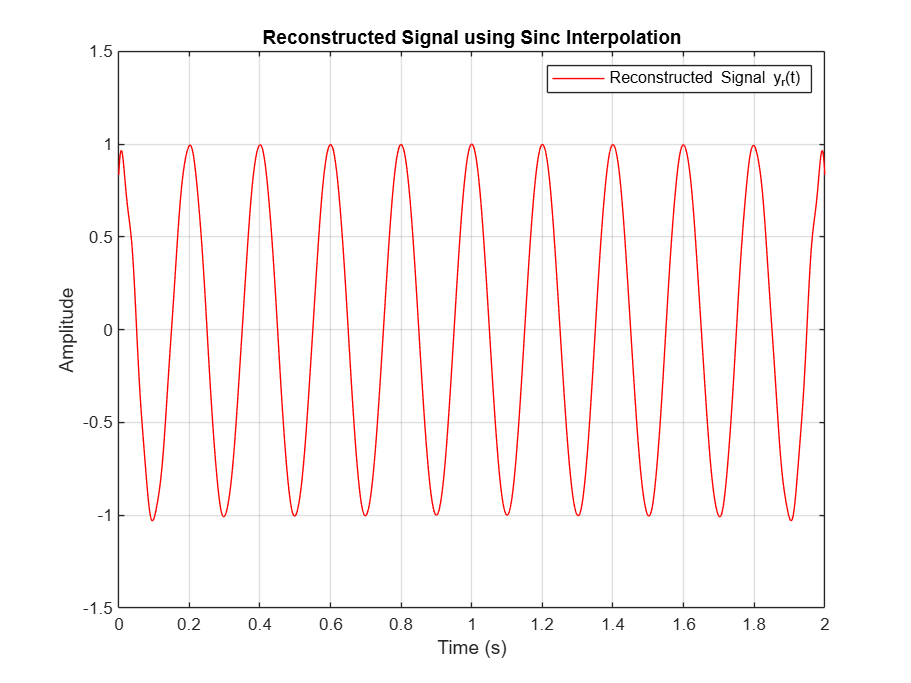

y_r = zeros(size(t_cont));
for n = 0:length(y_n)-1
    y_r = y_r + y_n(n+1) * sinc((t_cont - n*T) / T);
end
figure;
plot(t_cont, y_r, 'r'); 
xlabel('Time (s)');
ylabel('Amplitude');
title('Reconstructed Signal using Sinc Interpolation');
legend('Reconstructed Signal y_r(t)');
grid on;

**Observations:**

- **Frequency Component Analysis:**Plotting the individual low- and high-frequency components provides a clear visual reference, helping to illustrate the filter's effect on each part.

- **Sampling Process:**The continuous signal is sampled at a rate that meets the Nyquist criterion, allowing both frequency components to be represented accurately in the sampled data.

- **Filter Design with Impulse Response:**The filter’s impulse response is calculated using a sinc function, achieving a discrete approximation of an ideal low-pass filter that attenuates high frequencies.

- **Filtering by Convolution:**Convolution of the sampled signal with the low-pass filter’s impulse response results in a filtered signal that primarily contains the low-frequency component, confirming the filter's effectiveness.

- **Continuous-Time Approximation of Filtered Samples:**The filtered samples are visualized as narrow pulses to represent the sampled signal in continuous time, facilitating the interpretation of the sampled and filtered data.

- **Signal Reconstruction with Sinc Interpolation:**Sinc interpolation effectively reconstructs a continuous signal from the filtered samples, retaining the low-frequency component and closely matching the original low-frequency portion of the signal.

- **Edge Effects:**Minor mismatches at the edges of the reconstructed signal are observed, likely due to boundary effects introduced during convolution or sinc interpolation.

- **Conclusion on Signal Processing:**The experiment successfully demonstrates the principles of digital sampling, filtering, and reconstruction, showing how low-pass filtering can preserve desired low-frequency components while eliminating high-frequency noise.